# **Rapport TD2 : Convertion en noir et blanc par ACP**

Premièrement, on récupère les trois couches RGB que l'on transpose en trois vecteurs colonnes. On les convertit en reéls pour pouvoir travailler avec et on les rassemble dans la matrice X (de taille n*3). n1, n2 contiennent respectivement la longueur et la largeur de l'image.

clear all
clc
cd 'C:\Users\extra\OneDrive\Etudes\Projet Tut - Reconnaissance Faciale\Images\images'
I1=imread('lena_color_512.tif');
P1=I1(:,:,1);
P2=I1(:,:,2);
P3=I1(:,:,3);
[n1,n2]=size(P1);
W1=double(P1(:));
W2=double(P2(:));
W3=double(P3(:));
X=[W1 W2 W3];

On procède à l'ACP de cette nouvelle matrice:

- On centre la matrice X  --> Y.

- On calcule la matrice des variances / covariances V.

- On diagonalise la matrice V.

m=mean(X);
n=size(W1,1);
Y=X-ones(n,1)*m;
V=(1/n)*Y'*Y;
[U,vp1]=eig(V);
vp=diag(vp1);

V est la matrice des variances/covariances; U contient les vecteurs propres et vp les valeurs propres.

[vpo,I]=sort(vp,'descend'); % On range les valeurs propres selon l'ordre décroissant
P(:,:)=U(:,I(:)); % On range dans P les vecteurs propres suivant l'ordre des valeurs propres associés
Intot=sum(vpo); % Intot est l'inertie totale
tauxO=vpo/Intot; % Taux d'inertie de chaque axe

C=Y*P;


La projection (à 1 dimension) s'effectue selon un modéle affine de la forme Y = aX+b.

Les données étant centrées elles n'oscillent plus entre 0 et 255.

Soit M et m les points maximum et minimum. Pour que les données retrouvent des valeurs correctes allant de 0 a 255, Ymin = a*m + b = 0 et Ymax = a*M + b =255.

Par déduction, on peut retrouver les deux inconnus a=255/(M-m) et b = -a*m.

On obtient ainsi la nouvelle matrice Ynew contenant les nouvelles coordonnées.

Ynew=C(:,1); 

m=min(Ynew);
M=max(Ynew);
amplitude=M-m;
a=255/amplitude;
b=-a*m;
Xnew=a*Ynew+b;


On reconstruit la nouvelle image a partir de Xnew.

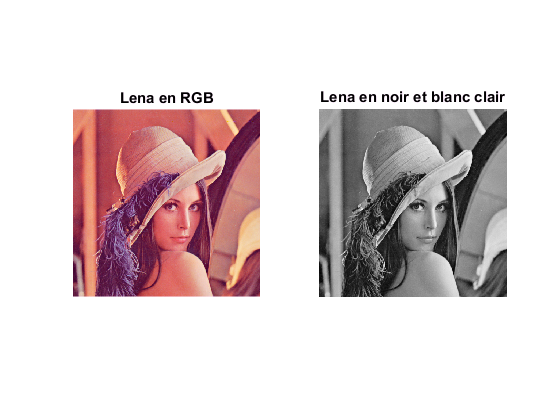

newIm1=uint8(zeros(n1,n2));
for (i=1:n1)
 newIm1(:,i)=uint8( Xnew( (i-1)*n2+1 : i*n2 )' );
end


figure

subplot(1,2,1)
imshow(I1) 
title('Lena en RGB')

subplot(1,2,2)
imshow(newIm1)
title('Lena en noir et blanc clair')